Spectral Sensitivity Functions for Digital Color Cameras (Sc)

wavelength: 400: 10: 720nm

clear; clc;

import file and get value

Sc_file =  '..\..\..\..\04 計畫\code\Step3\initial value\物理參數資料庫\Sc database.txt';
fid = fopen(Sc_file,'rt');
for i = 1:28
    line = fgetl(fid);
    name{i} = line;
    data{i} = cell2mat(textscan(fid,[repmat('%f ',[1,33])],'CollectOutput',1));
end

for i = 1:28
    Sc (:,:,i) = data{i};
end

Save whole dataset

fpath = 'C:\Users\lingoiapple\OneDrive - 國立台灣大學\JJJ\11 碩一 上下 2021-2022\study_水下攝影測量\水下攝影測量\04 計畫\模擬資料\';
save(strcat(fpath, 'Sc_database.mat'),"Sc")

Plot

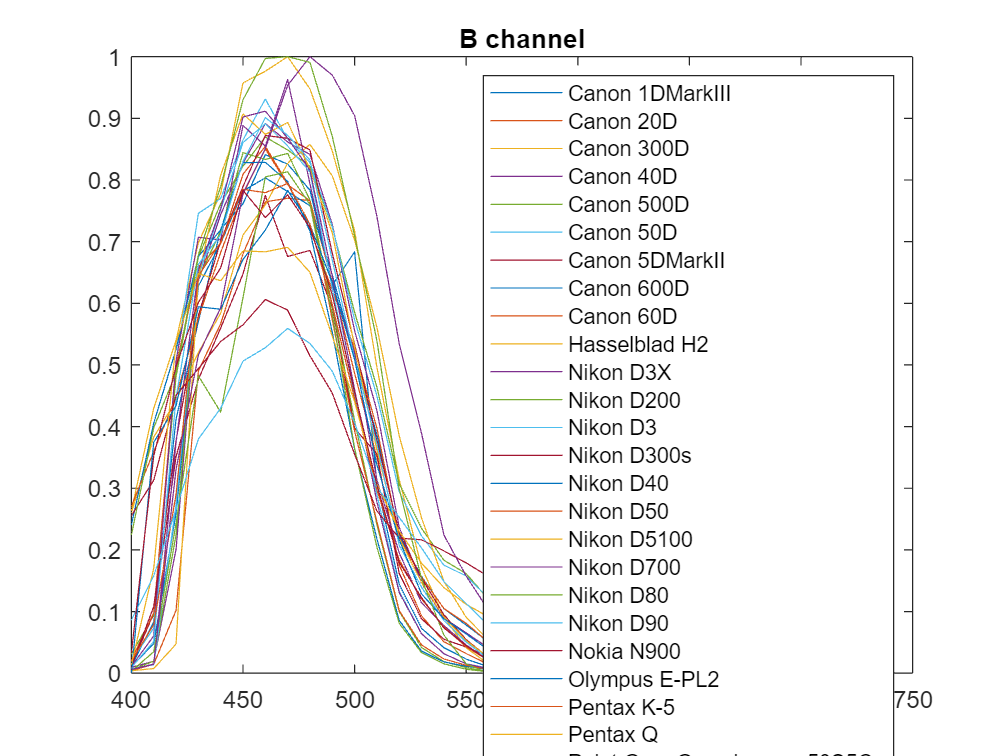

wl = 400:10:720;
figure
for i = 1:28
    plot(wl,Sc(3,:,i))
    hold on  
end
title('B channel')
legend(name)

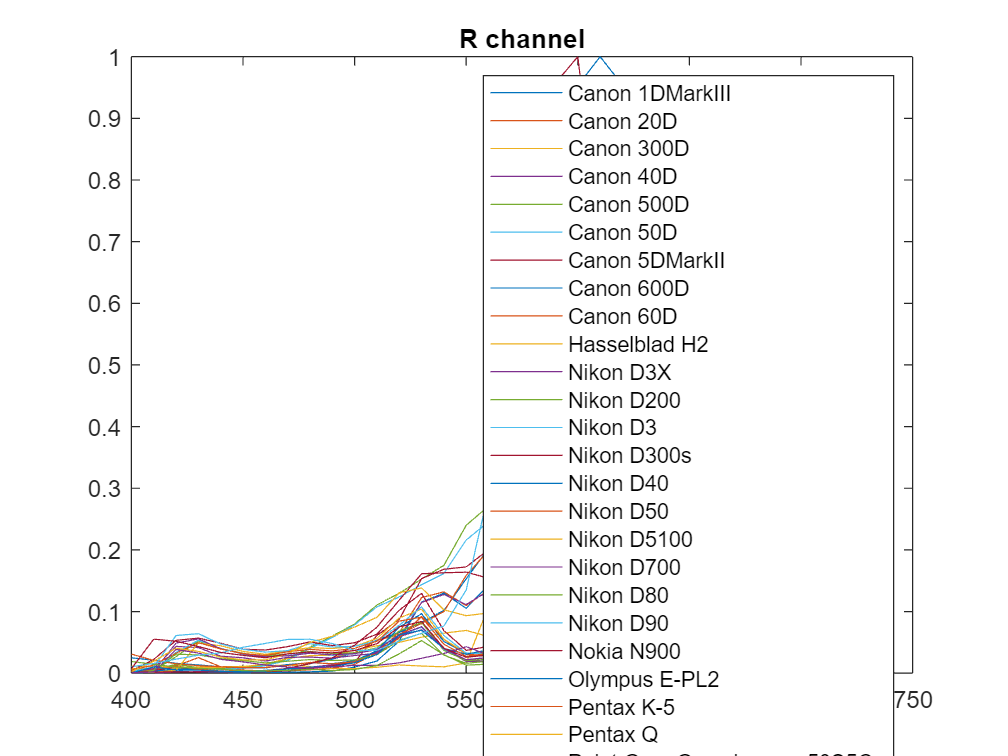


figure
for i = 1:28
    plot(wl, Sc(1,:,i))
    hold on  
end
legend(name)
title('R channel')

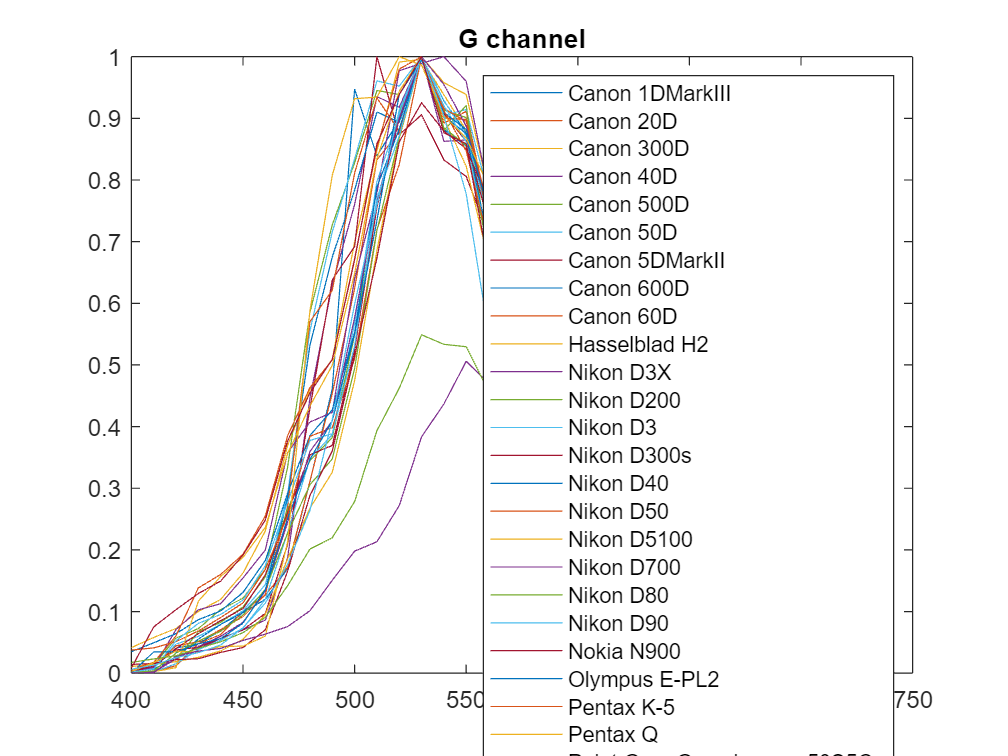


figure
for i = 1:28
    plot(wl, Sc(2,:,i))
    hold on  
end
title('G channel')
legend(name)

Sc RGB

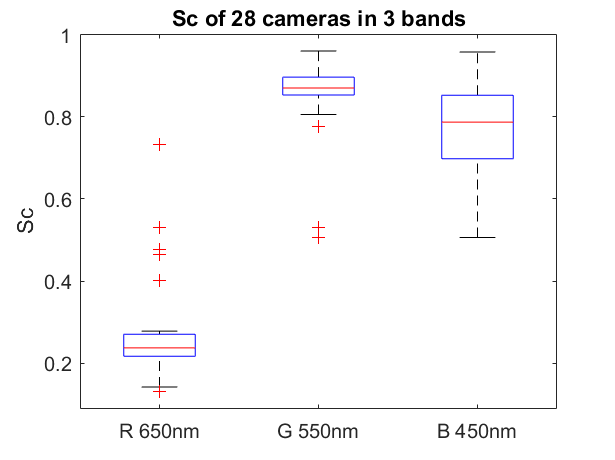

for i = 1:28
    Sc_RGB(i,:) = [Sc(1, 26, i) Sc(2, 16, i) Sc(3, 6, i)];
end

figure
boxplot(Sc_RGB,{'R 650nm','G 550nm','B 450nm'})
% xlabel('3 bands')
ylabel('Sc')
title('Sc of 28 cameras in 3 bands')


%  remove outliers
Sc_RGB_new = rmoutliers(Sc_RGB,"mean")

Sc_RGB_new =     0.2141    0.8772    0.7617
    0.2784    0.9112    0.6802
    0.2697    0.8804    0.9576
    0.2365    0.8649    0.8273
    0.2263    0.9013    0.8224
    0.2482    0.9143    0.8650
    0.2260    0.8057    0.6476
    0.2209    0.8553    0.7821
    0.2344    0.8982    0.8095
    0.1606    0.9387    0.7109


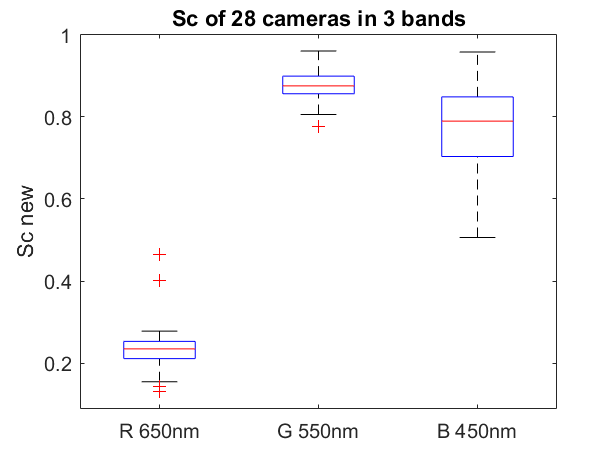


figure
boxplot(Sc_RGB_new,{'R 650nm','G 550nm','B 450nm'})
% xlabel('3 bands')
ylabel('Sc new')
title('Sc of 28 cameras in 3 bands')

Save Sc RGB

fpath = 'C:\Users\lingoiapple\OneDrive - 國立台灣大學\JJJ\11 碩一 上下 2021-2022\study_水下攝影測量\水下攝影測量\04 計畫\模擬資料\';
save(strcat(fpath, 'Sc_RGB.mat'),"Sc_RGB_new")

#### Transform matrix

%wavelength: 400: 10: 720nm
% Sc_new = mean(Sc,3)
Sc_new = Sc(:,:,20)

Sc_new =     0.0028    0.0101    0.0611    0.0641    0.0474    0.0387    0.0342    0.0366    0.0479    0.0424    0.0436    0.0526    0.0777    0.1075    0.0611    0.0326    0.0317    0.0823    0.3803    0.6952    0.6487    0.5834    0.4388    0.3828    0.2768    0.2214    0.1444    0.0653    0.0121    0.0023    0.0007    0.0003    0.0002
    0.0022    0.0067    0.0526    0.0808    0.0954    0.1186    0.1745    0.2775    0.3775    0.3886    0.5309    0.7710    0.8718    1.0000    0.9203    0.8620    0.6938    0.5725    0.3898    0.2626    0.1333    0.0684    0.0323    0.0229    0.0148    0.0116    0.0083    0.0048    0.0013    0.0004    0.0002    0.0001    0.0001
    0.0092    0.0514    0.4465    0.6632    0.7114    0.8299    0.9013    0.8725    0.8325    0.6703    0.5107    0.3710    0.2074    0.1394    0.0854    0.0505    0.0230    0.0123    0.0077    0.0049    0.0028    0.0021    0.0016    0.0021    0.0029    0.0040    0.0040    0.0022    0.0005    0.0001    0.0000    0.0000    0.000


% CIE XYZ tristimulus value
[lambda_2, xFcn, yFcn, zFcn] = colorMatchFcn('cie_1931');
num = 400:10:720;
for i = 1:length(num)
    n(i,:) = find(round(lambda_2)==round(num(i)));
end

for j = 1:length(n)
    xFcn_new(j) = xFcn(n(j));
    yFcn_new(j) = yFcn(n(j));
    zFcn_new(j) = zFcn(n(j));
end

% A matrix
for i = 1:numel(xFcn_new)
    A(3*i-2,:) = xFcn_new(i);  
    A(3*i-1,:) = yFcn_new(i);  
    A(3*i,:) = zFcn_new(i);  
end

% B matrix
for i = 1:numel(xFcn_new)
    B(3*i-2:3*i,:) = blkdiag(Sc_new(:,i)',Sc_new(:,i)',Sc_new(:,i)');
end

x = B\A

x =     1.6424
    0.1972
    0.0813
    0.7596
    1.0003
   -0.2536
    0.0871
   -0.3126
    1.6800


x = reshape(x,[3,3])'

x =     1.6424    0.1972    0.0813
    0.7596    1.0003   -0.2536
    0.0871   -0.3126    1.6800


#### Check

x * Sc_new

ans =     0.0211    0.0435    0.1039    0.1497    0.1537    0.1701    0.1812    0.2017    0.2218    0.2146    0.2212    0.2392    0.2657    0.3004    0.2566    0.2465    0.2544    0.3818    0.7734    1.0966    1.0509    0.9454    0.8070    0.7175    0.5758    0.4519    0.2932    0.1731    0.0808    0.0417    0.0176    0.0061    0.0032
   -0.0041   -0.0133   -0.0363   -0.0653   -0.0684   -0.0728   -0.0431    0.0644    0.2125    0.3223    0.5094    0.7139    0.8506    0.9636    0.8893    0.8677    0.7451    0.7148    0.7386    0.7621    0.6158    0.4953    0.3921    0.3392    0.2683    0.2087    0.1349    0.0810    0.0389    0.0203    0.0089    0.0032    0.0017
    0.1178    0.2719    0.6720    1.0765    1.1902    1.3769    1.4379    1.3953    1.2679    1.0150    0.7033    0.3622    0.0632   -0.1030   -0.1658   -0.2051   -0.1887   -0.1583   -0.0801   -0.0176    0.0234    0.0431    0.0496    0.0499    0.0426    0.0367    0.0249    0.0152    0.0073    0.0039    0.0016    0.0005    0.0003


reshape(A,[3,33])

ans =     0.0143    0.0435    0.1344    0.2839    0.3483    0.3362    0.2908    0.1954    0.0956    0.0320    0.0049    0.0093    0.0633    0.1655    0.2904    0.4334    0.5945    0.7621    0.9163    1.0263    1.0622    1.0026    0.8544    0.6424    0.4479    0.2835    0.1649    0.0874    0.0468    0.0227    0.0114    0.0058    0.0029
    0.0004    0.0012    0.0040    0.0116    0.0230    0.0380    0.0600    0.0910    0.1390    0.2080    0.3230    0.5030    0.7100    0.8620    0.9540    0.9950    0.9950    0.9520    0.8700    0.7570    0.6310    0.5030    0.3810    0.2650    0.1750    0.1070    0.0610    0.0320    0.0170    0.0082    0.0041    0.0021    0.0010
    0.0679    0.2074    0.6456    1.3856    1.7471    1.7721    1.6692    1.2876    0.8130    0.4652    0.2720    0.1582    0.0782    0.0422    0.0203    0.0087    0.0039    0.0021    0.0017    0.0011    0.0008    0.0003    0.0002    0.0000    0.0000         0         0         0         0         0         0         0         0
